clear;clc;close all

## Compare Cluster Assignments to Clusters

Load the sample data.

load fisheriris

Compute four clusters of the Fisher iris data using Ward linkage and ignoring species information.

Z = linkage(meas,'ward','euclidean');
c = cluster(Z,'maxclust',3);

See how the cluster assignments correspond to the three species.

crosstab(c,species)

ans =      0     1    35
     0    49    15
    50     0     0


Display the first five rows of Z.

firstfive = Z(1:5,:)

firstfive =   102.0000  143.0000         0
    8.0000   40.0000    0.1000
    1.0000   18.0000    0.1000
   10.0000   35.0000    0.1000
  129.0000  133.0000    0.1000


Create a dendrogram plot of `Z` .

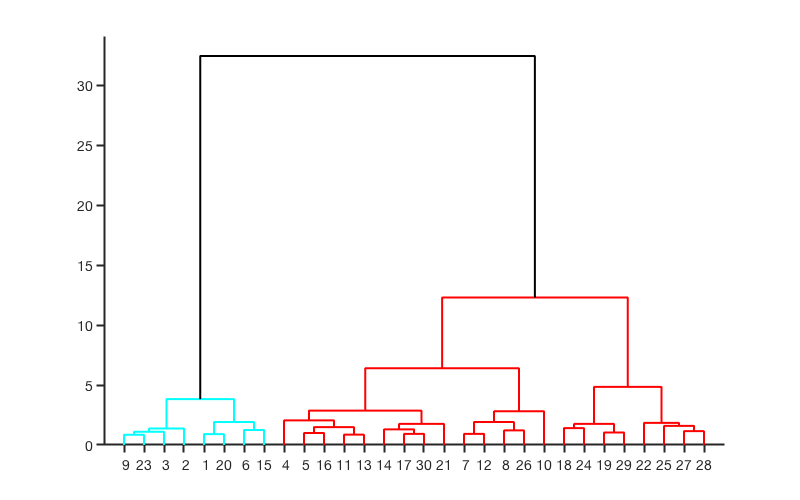

H=dendrogram(Z,'ColorThreshold','default');set(H,'LineWidth',2)
set(gca,'FontSize',14); set(gca,'TickDir','out'); set(gca,'LineWidth',2);
print('-depsc2','Dendogram.eps');% save to an eps file

## see which species are in each cluster

uc=unique(c);
for i=1:length(uc)
   disp(['Class ' num2str(uc(i))])
   iwant=find(c==uc(i));
   species{iwant}
end

Class 1


ans = 'versicolor'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

Class 2


ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'versicolor'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

ans = 'virginica'

Class 3


ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

ans = 'setosa'

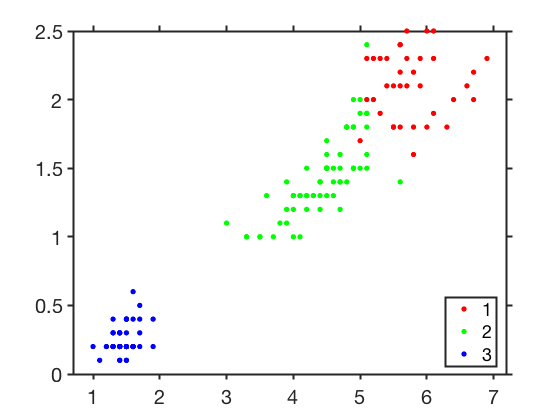


figure
gscatter(meas(:,3),meas(:,4),c)
set(gca,'FontSize',20); set(gca,'TickDir','out'); set(gca,'LineWidth',2);
print('-depsc2','HeirarchicalClusteringExample-a.eps');% save to an eps file

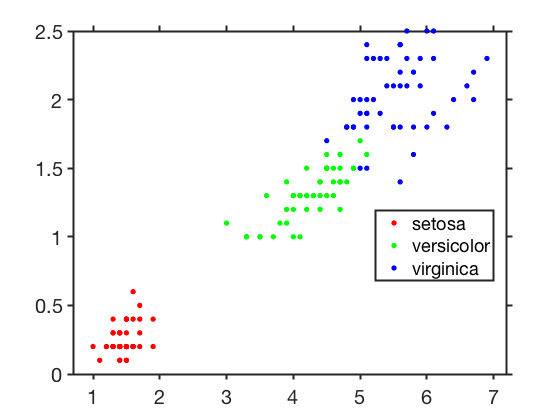


figure
gscatter(meas(:,3),meas(:,4),species)
set(gca,'FontSize',20); set(gca,'TickDir','out'); set(gca,'LineWidth',2);
print('-depsc2','HeirarchicalClusteringExample-b.eps');% save to an eps file